# Comparaison des méthodes de commande

## A) Initialisation

### 1) Création du robot

- Chariot

S0 = Link('revolute', 'alpha', -pi/2);
S1 = Link('prismatic', 'qlim', [0,0.2]);
S1bis = Link('revolute', 'alpha', pi/2, 'offset', pi/2, 'qlim', 0);
S2 = Link('prismatic', 'qlim', [0,0.2], 'alpha', pi/2);
S2bis = Link('revolute', 'alpha', -pi/2, 'offset', pi/2, 'qlim', 0);

- Paramètres géométriques

D0 = 0.077;
D1 = 0.128;
d1 = 0.024;
D2 = 0.124;
D3 = 0.126;

- Bras articulé

L0 = Link('revolute', 'd', D0, 'alpha', 0, 'offset', 0);
L0bis = Link('revolute', 'd', 0, 'offset', 0, 'alpha', pi/2);
L1 = Link('revolute', 'a', -D1, 'offset', -pi/2, 'alpha', 0);
L1bis = Link('revolute', 'a', d1, 'qlim', 0, 'offset', pi/2);
L2 = Link('revolute', 'a', D2, 'offset', 0);
L3 = Link('revolute', 'a', D3, 'offset', 0, 'alpha', -pi/2);

- Assemblage

Robot = SerialLink([S0 S1 S1bis S2 S2bis L0 L0bis L1 L1bis L2 L3], 'name', 'Robot');

### 2) Trajectoire de référence

addpath('Trajectoires_test')

- Durée de simulation (en seconde)

Tsim = 50;

- Vecteur de temps

tstep = 0.01;
t = 0:tstep:Tsim;

- Vecteurs positions

x = zeros(1, length(t));
y = zeros(1, length(t));
z = zeros(1, length(t));

- Trajectoire

[z, y, x] = creneau(0.1, 0.1, 0.05, t, 1, 0.05)

z =     0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245    0.0250


y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500


## B) Calcul de la trajectoire de commande

### 1) Transformation en signaux

xref = struct();
xref.signals.values = x'; 
xref.time = t';

yref = struct();
yref.signals.values = y';
yref.time = t';

zref = struct();
zref.signals.values = z'; 
zref.time = t';

### 2) Coefficient K

K = 10;

### 3) Exécution Simulink

out_moy = sim("methode_des_moyennes.slx" );
out_ass = sim("methode_asservissement.slx");

## C) Analyse des résultats

### 1) Récupération des signaux de sortie

- Consignes du bras

q0_ass = out_ass.q0;
q1_ass = out_ass.q1;
q2_ass = out_ass.q2;
q3_ass = out_ass.q3;

q0_moy = out_moy.q0;
q1_moy = out_moy.q1;
q2_moy = out_moy.q2;
q3_moy = out_moy.q3;

- Consigne du chariot

x_char_ass = out_ass.x_char;
y_char_ass = out_ass.y_char;

x_char_moy = out_moy.x_char;
y_char_moy = out_moy.y_char;

### 2) Récupération des valeurs

- Consignes du bras

q0_ass_val = q0_ass.Data;
q1_ass_val = q1_ass.Data;
q2_ass_val = q2_ass.Data;
q3_ass_val = q3_ass.Data;

q0_moy_val = q0_moy.signals.values;
q1_moy_val = q1_moy.signals.values;
q2_moy_val = q2_moy.signals.values;
q3_moy_val = q3_moy.signals.values;

- Consigne du chariot

x_char_ass_val = x_char_ass.Data;
y_char_ass_val = y_char_ass.Data;

x_char_moy_val = x_char_moy.signals.values;
y_char_moy_val = y_char_moy.signals.values;

- Temps de simulation

t_ass = out_ass.tout;
t_moy = out_moy.tout;

### 3) Affichage

- Consigne du bras

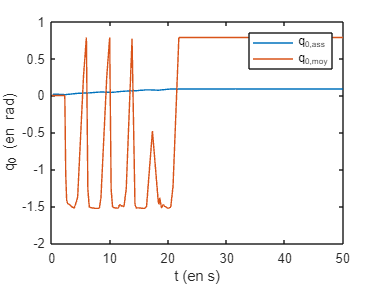

plot(t_ass, q0_ass_val, t_moy, q0_moy_val)
xlabel('t (en s)')
ylabel('q_0 (en rad)')
legend(['q_0,ass'; 'q_0,moy'])

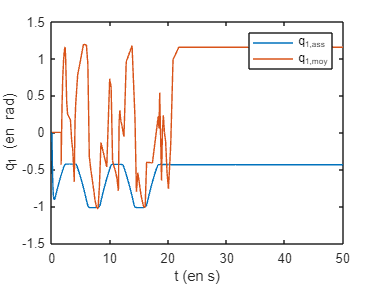


plot(t_ass, q1_ass_val, t_moy, q1_moy_val)
xlabel('t (en s)')
ylabel('q_1 (en rad)')
legend(['q_1,ass'; 'q_1,moy'])

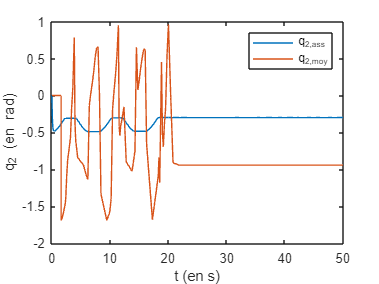


plot(t_ass, q2_ass_val, t_moy, q2_moy_val)
xlabel('t (en s)')
ylabel('q_2 (en rad)')
legend(['q_2,ass'; 'q_2,moy'])

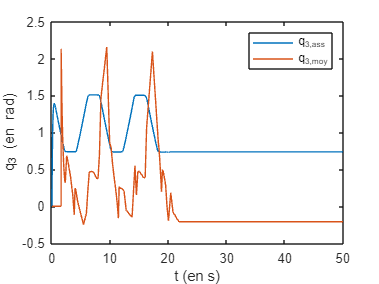


plot(t_ass, q3_ass_val, t_moy, q3_moy_val)
xlabel('t (en s)')
ylabel('q_3 (en rad)')
legend(['q_3,ass'; 'q_3,moy'])

- Consigne du chariot

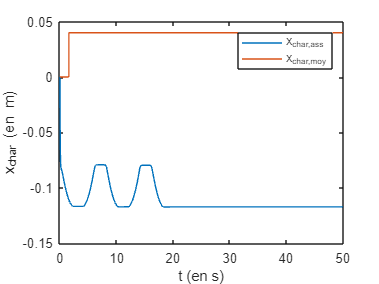

plot(t_ass, x_char_ass_val, t_moy, x_char_moy_val)
xlabel('t (en s)')
ylabel('x_char (en m)')
legend(['x_char,ass'; 'x_char,moy'])

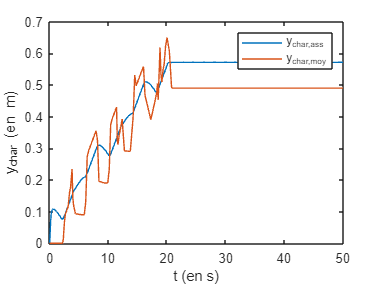


plot(t_ass, y_char_ass_val, t_moy, y_char_moy_val)
xlabel('t (en s)')
ylabel('y_char (en m)')
legend(['y_char,ass'; 'y_char,moy'])

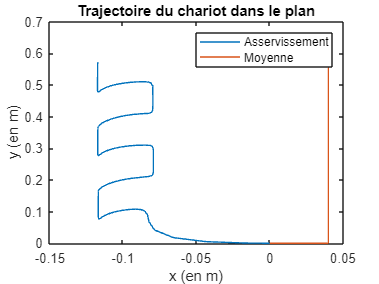


plot(x_char_ass_val, y_char_ass_val, 'DisplayName', 'Asservissement')
hold on
plot(x_char_moy_val, y_char_moy_val, 'DisplayName', 'Moyenne')
hold off
title('Trajectoire du chariot dans le plan')
xlabel('x (en m)')
ylabel('y (en m)')
legend